load uspsDigits.mat;


%ima(testDigits(:,:,1))

randImgIndex = randi(2007)

randImgIndex = 1705


indexFour = find(testAns == 4);

indexFour =     14
    23
    48
    63
    93
   110
   130
   154
   171
   175



mean(testDigits(indexFour),3);
sumFour = zeros(16,16,1);
for c = 1:length(indexFour)
    indexValue = indexFour(c);
    testDigits(:,:,indexValue);
    sumFour(:,:,1) = sumFour(:,:,1) + testDigits(:,:,indexValue);
end
meanFour = sumFour./length(indexFour);

meanFour =     0.0012    0.0060    0.0115    0.0412    0.0817    0.1062    0.0845    0.0668    0.0888    0.1554    0.2336    0.2167    0.1346    0.0629    0.0400    0.0092
    0.0010    0.0166    0.0482    0.1142    0.1970    0.2265    0.1740    0.1196    0.1478    0.2365    0.3532    0.3575    0.2313    0.1307    0.0800    0.0293
    0.0011    0.0294    0.0817    0.1928    0.3172    0.3287    0.2057    0.1446    0.1756    0.2830    0.4034    0.4116    0.2750    0.1848    0.1158    0.0480
    0.0078    0.0373    0.1218    0.2913    0.4339    0.3932    0.2194    0.1392    0.1939    0.3272    0.4523    0.4337    0.2926    0.2061    0.1145    0.0432
    0.0133    0.0689    0.2046    0.3975    0.5175    0.4168    0.2180    0.1482    0.2224    0.3626    0.4909    0.4522    0.3014    0.1931    0.0956    0.0224
    0.0223    0.1134    0.2918    0.4946    0.5519    0.4101    0.2300    0.1801    0.2556    0.4053    0.5456    0.4807    0.3078    0.1735    0.0650    0.0085
    0.0460    0.1579   

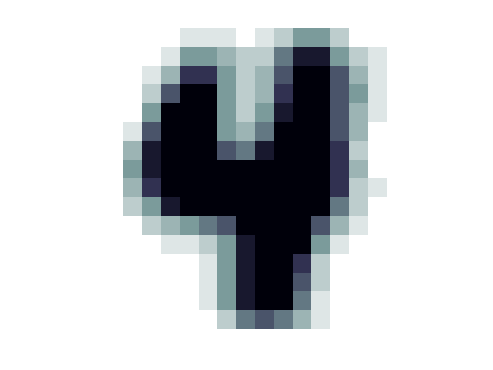

ima(meanFour)

randImgIndex = randi(2007)

randImgIndex = 1818

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;
for c = 1:2007
    if c ~= randImgIndex
        tempDiff = abs(norm(kolTestDigits(:,:,c)) - norm(kolTestDigits(:,:,randImgIndex)));
        if tempDiff < savedDiff
            savedDiff = tempDiff;
            savedIndex = c;
        end
    end
end 
savedIndex

savedIndex = 216

savedDiff

savedDiff = 0.0015

testAns(randImgIndex)

ans = 9

testAns(savedIndex)

ans = 0

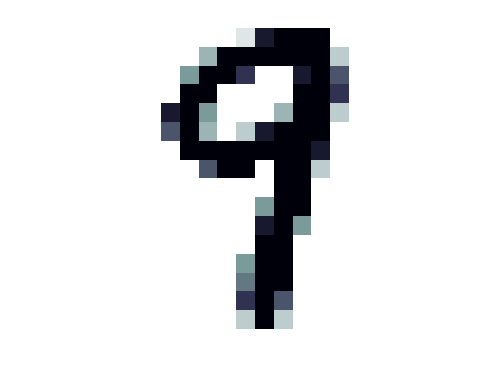

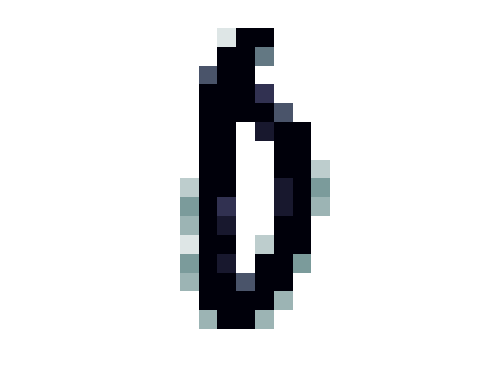

ima(testDigits(:,:,randImgIndex))
ima(testDigits(:,:,savedIndex))

randImgIndex = randi(2007)

randImgIndex = 1521

kolTestDigits = reshape(testDigits, [256, 1, 2007]);

savedIndex = 0;
savedDiff = 1e10;

nClosesNeighbooorIndex = [0;0;0;0;0];
nClosesNeighbooorValues = [savedDiff;savedDiff;savedDiff;savedDiff;savedDiff];

for n = 1:5
    for c = 1:2007
        if c ~= randImgIndex 
            
        end
    end 
end



nClosesNeighbooorIndex

nClosesNeighbooorIndex =      0
     0
     0
     0
     0


nClosesNeighbooorValues

nClosesNeighbooorValues = 	1.0e+10 *

    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
